We are trying to create a simulation of how we believe particles fluctuate when effected by sound generation. Sound generation is the vibration created by instruments or speakers disturbance to surrounding air particles.   

First we must set the random walk parameters of the number of particles we will be simulating, their steps and the size of those steps. In this case we have 5 Particles, 82 Steps and the size will be 1 as we want the particle to move once per beat. 

% Random Walk Parameters
Particles = 5;     % Number of particles
Steps = 82;       % Number of steps for each particle
stepSize = 1;         % Step size for each movement


The particles will be moving to the song Hot Cross Bun. First we will audio read the song and process the sound into its data and rate so we can find its duration. Ensure the sound data is converted to double so that it is in the form of a floating-point. 

% Sound Processing
[y, Fs] = audioread('hot_cross_buns.wav');
y = double(y);  % Convert to double (floating-point)
soundDuration = length(y) / Fs;

The function detectBeats will be use to identify the notes in the sounds data

% Detect beats or notes
onsets = detectBeats(y, Fs);  % Function to detect beats/notes

Now we will generate the random walks and a figure to visualise the particles in. The figure will depict the particle's movement each step.

% Generate random walks
rng('default');  % Reset random number generator
particlePositions = zeros(Particles, Steps + 1);  % Particle positions matrix
% Visualization
figure;
title('Random Walk Movement');
xlabel('Step');
ylabel('Position');
axis([1 Steps+1 -50 50]);  % Set the axis limits
% Initialize plot handles for each particle
h = gobjects(Particles, 1);
for p = 1:Particles
    h(p) = plot(1, particlePositions(p, 1));  % Plot initial position for each particle
    hold on;
end
hold off;

Play the audio file so it can be played with the simulation when run.

% Play the audio file once
sound(y, Fs/2);

Finally the particles need to be animated so their movement can be visualised. Each step for each particle needs to be mapped by its beat and and corresponding random walk movement.

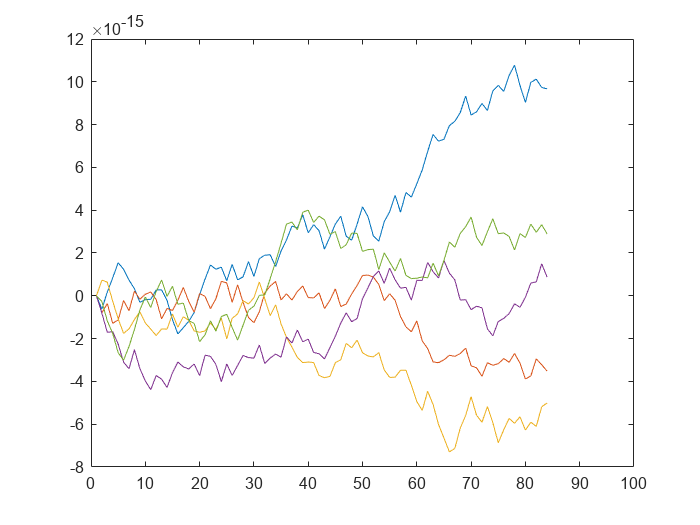

% Animation
for s = 1:Steps + 1
    for p = 1:Particles
        if s <= length(onsets)
            % Map each beat/note to a corresponding random walk movement
            beatTime = onsets(s) * soundDuration;
            particlePositions(p, s + 1) = particlePositions(p, s) + stepSize * randomWalk(beatTime);
        else
            % If there are no more beats, continue random walking until
            % sound stops
            particlePositions(p, s + 1) = particlePositions(p, s) + stepSize * randomWalk(soundDuration);
        end
    end
    
    % Update positions of all particles
    for p = 1:Particles
        set(h(p), 'XData', 1:s+1, 'YData', particlePositions(p, 1:s+1));
    end
    xlim([0 100])
    drawnow;
end